# Finite Difference Method - 1D Poisson Equation

Use the FDM to solve Poisson's equation for $x \in [a,b]$

## Step 1: Dirichlet BCs


$$    \left\{
     \begin{array}{c}
          \frac{\mathrm{d^2}\varphi}{\mathrm{d}x^2} - t(x)= 0 \\
         \varphi(a) = \varphi_a\\
         \varphi(b) = \varphi_b\\
       \end{array}$$


Create an m-function "FDM_1D_s1" with the following I/O scheme:

- input: geometry (a, b, number of nodes); boundary conditions (boundary condition type and value in a and b); uniform source term $t(x)=t$

- output: x (coordinates of nodes), phi (computed values of uknown function)

Use the function to simulate a case where $a = 0; b = 1; n = 11; \varphi_a = 1; \varphi_b = 0; t = 0
$.

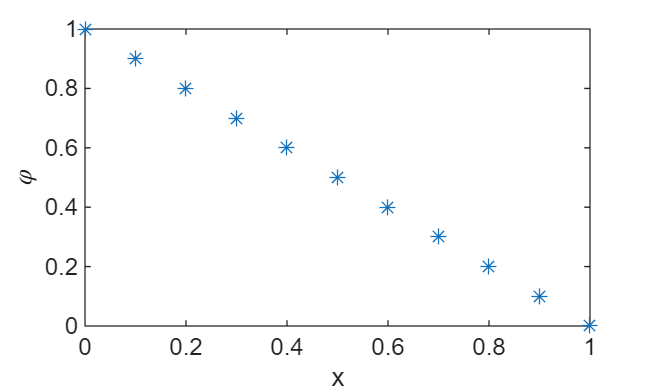

geom.a = 0; % left boundary of interval
geom.b = 1; % right boundary of interval
geom.n = 11; % number of nodes
BC.a.type = 'D'; % dirichlet BC in a
BC.a.val = 1; % value of BC in a
BC.b.type = 'D';
BC.b.val = 0;

t = 0; % zero source term

[x,phi] = FDM_1D_s1(geom,BC,t);

plot(x,phi,'*')
xlabel('x'); ylabel('$\varphi$','Interpreter','latex')

Set t = 5 and check with the exact solution by plotting the absolute error:


$$    \varphi(x) = \frac{t}{2} x^2 + \left( \frac{\varphi_b - \varphi_a - \frac{t}{2} L^2}{L} \right)x + \varphi_a$$


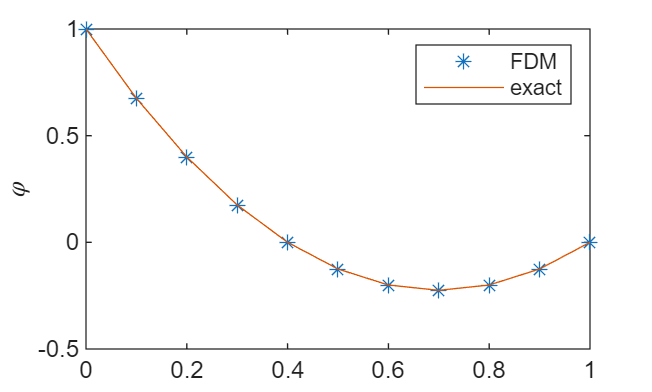

t = 5;
[x,phi] = FDM_1D_s1(geom,BC,t);

L = geom.b-geom.a; % length of domain
phi_ex = t/2*x.^2 + (BC.b.val-BC.a.val-t/2*L^2)/L*x + BC.a.val;

plot(x,phi,'*',x,phi_ex,'-');
ylabel('$\varphi$','Interpreter','latex')
legend('FDM','exact')

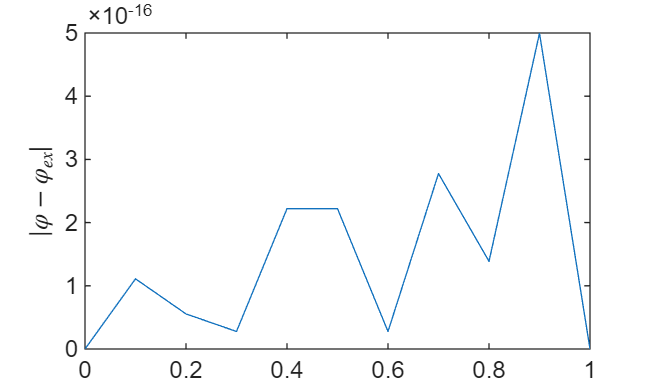


% check the absolute error
err = abs(phi - phi_ex');
plot(x,err);
ylabel('$|\varphi - \varphi_{ex}|$','Interpreter','latex')

Compare the solutions obtained by setting $t=0
$ and $t = 10$.

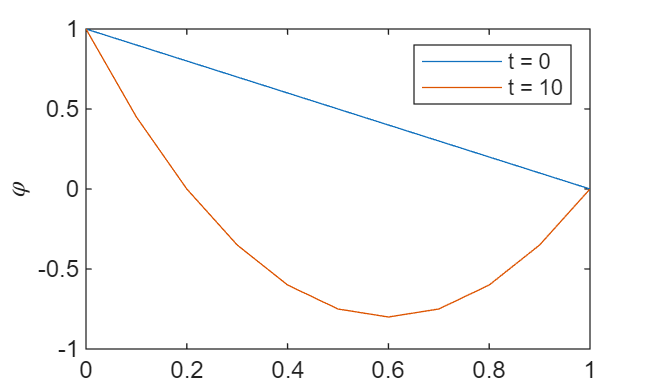

t = 0;
[x,phi_0] = FDM_1D_s1(geom,BC,t);

t = 10;
[x,phi_10] = FDM_1D_s1(geom,BC,t);

plot(x,phi_0,x,phi_10);
ylabel('$\varphi$','Interpreter','latex')
legend('t = 0','t = 10')

## Step 2: Neumann BCs (symmetry)

Create a new function FDM_1D_s2 that allows to use Neumann boundary conditions:


$$    \left\{
     \begin{array}{c}
          \frac{\mathrm{d^2}\varphi}{\mathrm{d}x^2} - t(x)= 0 \\
         \varphi(a) = \varphi_a\\
         \left.\frac{\mathrm{d}\varphi}{\mathrm{d}x}\right|_{x=b}=\varphi'_b
       \end{array}$$


To discretize the Neumann BC (node n) use:


$$\varphi_{n-1}-\varphi_{n}= \Delta x \left(\frac{t_{n}}{2}\Delta x - \varphi_b' \right)$$


Simulate a half-domain with a zero Neumann BC on one side using the developed code

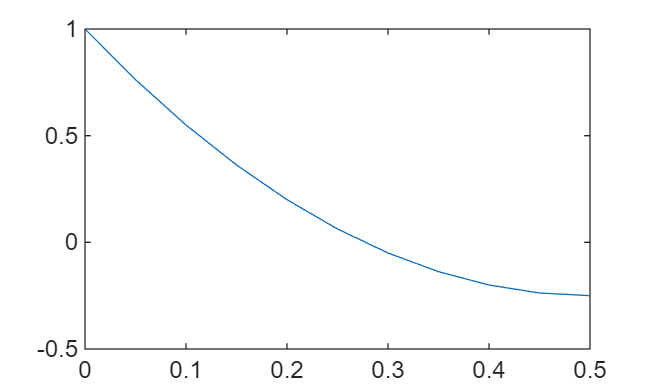

geom.b = 0.5; % half the domain lenght
BC.b.type = 'N';
BC.b.val = 0;

[x,phi] = FDM_1D_s2(geom,BC,t);
plot(x,phi)

Compare it with a symmetrical Dirichlet condition on a corresponding full domain.

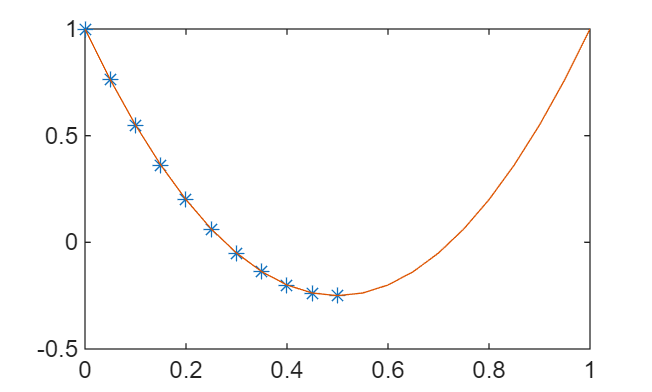

geom.b = 1; % half the domain lenght
geom.n = 21;
BC.b.type = 'D';
BC.b.val = 1; % make it symmetric

[x_full,phi_full] = FDM_1D_s2(geom,BC,t);

plot(x,phi,'*',x_full,phi_full)

## Step 3: post-processing computation of $\frac{d\varphi}{dx}$

Compute the gradient of the unknown function $\varphi$ using finite difference formulas and add that to the outputs of the FDM_1D_s2 function. Observe the difference when $t=0$ and when $t = 2\cdot10^3$.